clc;clear all;close all;
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


A = [0 1; 3 4] 

A =      0     1
     3     4


B =[0; 2]

B =      0
     2


C = [1 0]

C =      1     0


D = [0]

D = 0


Q=diag([1000 1]);
R=0.01;
K=lqr(A,B,Q,R)

K =   317.7313   22.5361


Kr=(-(C-D*K)*(A-B*K)^-1*B+D)^-1

Kr = 316.2313


ACL=A-B*K;
BCL=B*Kr;
CCL=C-D*K;
DCL=D*Kr;
GCL1=ss(ACL,BCL,CCL,DCL)

GCL1 =
 
  A = 
           x1      x2
   x1       0       1
   x2  -632.5  -41.07
 
  B = 
          u1
   x1      0
   x2  632.5
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Proper

polos = pole(GCL1)

polos =  -20.5361 +14.5166i
 -20.5361 -14.5166i


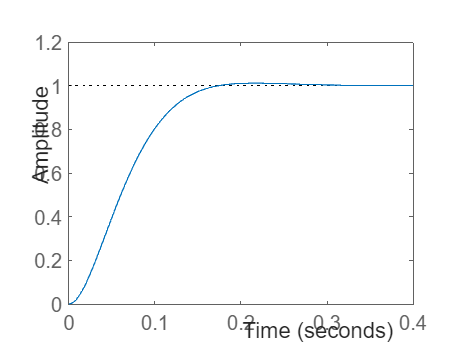

step(GCL1)



P2 = 1/(s^2+2*s+3)

P2 =
 
        1
  -------------
  s^2 + 2 s + 3
 
Continuous-time transfer function.
Model Properties



GOL1=P2*GCL1

GOL1 =
 
  A = 
           x1      x2      x3      x4
   x1      -2    -1.5     0.5       0
   x2       2       0       0       0
   x3       0       0       0       1
   x4       0       0  -632.5  -41.07
 
  B = 
          u1
   x1      0
   x2      0
   x3      0
   x4  632.5
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


A1=GOL1.A

A1 =    -2.0000   -1.5000    0.5000         0
    2.0000         0         0         0
         0         0         0    1.0000
         0         0 -632.4626  -41.0722


B1=GOL1.B

B1 =          0
         0
         0
  632.4626


C1=GOL1.C

C1 =      0     1     0     0


D1=GOL1.D

D1 = 0


Qy=10000;
Q1=C1'*Qy*C1;
R1=0.0001;
K1=lqr(A1,B1,Q1,R1)

K1 = 1.0e+03 *

    0.9990    9.9596    0.0125    0.0001


Kr1=(-(C1-D1*K1)*(A1-B1*K1)^-1*B1+D1)^-1;
%2do paso L lq
G1=eye(4)

G1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Qw=0.01*diag([1 1 1 1]);
Vv=0.0001;
L1=lqe(A1,G1,C1,Qw,Vv)

L1 =     2.2792
   10.4459
    0.0052
   -0.1426


%3er paso ss
ACL2=[A1 -B1*K1;L1*C1 A1-B1*K1-L1*C1]

ACL2 = 1.0e+06 *

   -0.0000   -0.0000    0.0000         0         0         0         0         0
    0.0000         0         0         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0
         0         0   -0.0006   -0.0000   -0.6318   -6.2991   -0.0079   -0.0001
         0    0.0000         0         0   -0.0000   -0.0000    0.0000         0
         0    0.0000         0         0    0.0000   -0.0000         0         0
         0    0.0000         0         0         0   -0.0000         0    0.0000
         0   -0.0000         0         0   -0.6318   -6.2991   -0.0085   -0.0001


BCL2=[B1*Kr1;B1*Kr1];
CCL2=[C1 -D1*K1];
DCL2=[D1*Kr1];

polos_observador = eig(A1 - L1*C1)

polos_observador =   -3.0175 + 0.0000i
  -9.4284 + 0.0000i
 -20.5361 +14.5166i
 -20.5361 -14.5166i


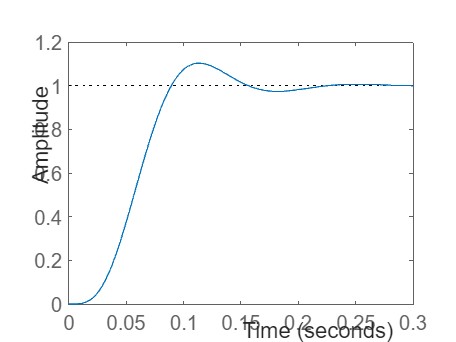



GCL2=ss(ACL2,BCL2,CCL2,DCL2);
step(GCL2)

Polos = pole(GCL2)

Polos =  -19.8856 +45.2240i
 -19.8856 -45.2240i
 -47.1760 +19.1259i
 -47.1760 -19.1259i
  -3.0175 + 0.0000i
  -9.4284 + 0.0000i
 -20.5361 +14.5166i
 -20.5361 -14.5166i
